# Linealización y control de un modelo de presa-depredador 

Tomaremos el modelo presa depredador:


$$\dot{P}(t)= \alpha P(t) - \beta P(t)D(t)\\
\dot{D}(t)= \delta P(t) D(t) - \gamma D(t)$$


**Con los siguientes parámetros y estados:**

$P(t)$: Número de presas en el tiempo

$D(t)$: Depredadores en el tiempo

$\alpha$: Tasa instantánea de aumento de presas en ausencia de depredadores

$\beta$: Tasa de cacería de número de presas por depredador

$\delta$: Tasa de aumento de depredadores por presa cazada

$\gamma$: Tasa instantánea de disminución de depredadores en ausencia de presas

**1.** Definición de los parámetros del modelo junto a sus condiciones iniciales

addpath("Modelos")
%condiciones iniciales
P0 = 1;
D0 = 2;

%Parametros
alpha = 1;
beta = 1;
delta = 1;
gamma = 1;

%Tiempo de simulacion
Time = 50;

**2. **Definición de los parámetros carácteristicos de la entrada, que en este caso es la entrada de tipo seno

%Entrada
u = 1;
Amplitude = 0.5;
Frequency = 1;

**3.** Simulación con la entrada seleccionada

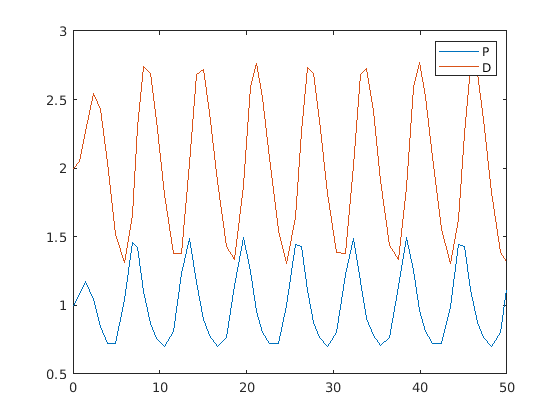

options = simset('SrcWorkspace','current');
sim('PresaDepredador',[],options);

plot(t,P,t,D)
legend("P","D")

**4.** Definición de los puntos de equilibrio con la entrada seleccionada

P_eq = 1.097;
D_eq = 2.021;

N_eq = [P_eq, D_eq];

**5.** Linealización con al función *linmod *utilizando los modelos base para obtener los valores del jacobiano 

ul = 1;
u = ul;

[A,B,C,D] = linmod("PresaDepredador_base", N_eq, u);

options = simset('SrcWorkspace','current');
sim('PresaDepredador_lineal',[],options);

**6.** Comparación del modelo lineal con el no lineal para $P$

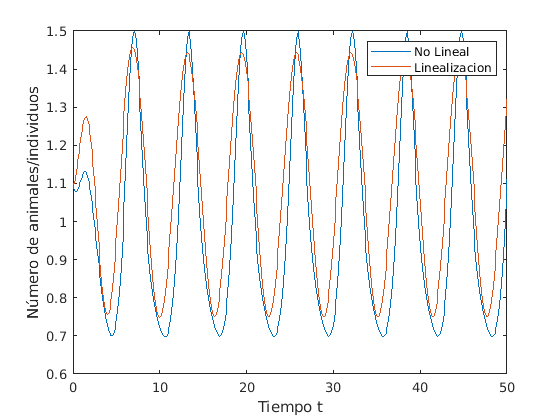

figure
plot(t,P,t,LP)
legend('No Lineal', 'Linealizacion')
ylabel('Número de animales/individuos')
xlabel('Tiempo t')

**7.** Comparación del modelo lineal con el no lineal para $D$

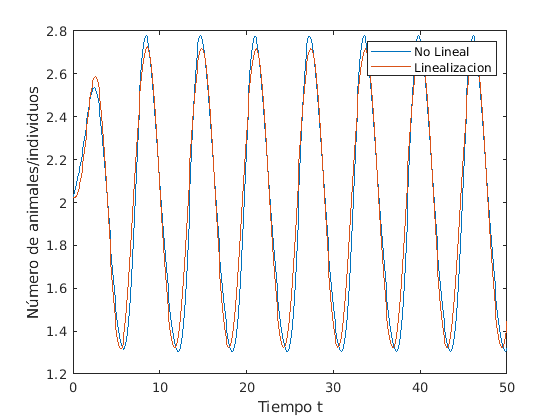

figure
plot(t,D,t,LD)
legend('No Lineal', 'Linealizacion')
ylabel('Número de animales/individuos')
xlabel('Tiempo t')

**8.** Se identifica si el punto de equilibrio del modelo linealizado es estable

eig(A)

ans =   -0.4620 + 1.3801i
  -0.4620 - 1.3801i


**9.** Se define el control a partir de los polos de la matriz

K = place(A,B,[1, -1])

K =    -0.9240   -1.5871


**10. **Se realiza la simulación del modelo con el control utilizando como señal de referencia una función tipo seno

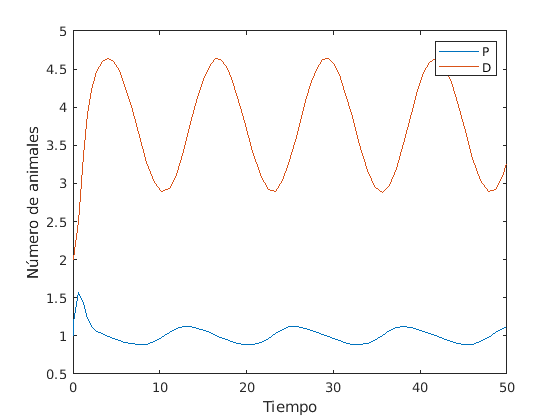

% Parámetros de señal de referencia
Time = 50;
u = 4;
Amplitude = 1;
Frequency = 0.5;

%simulacion del modelo con control
options = simset('SrcWorkspace','current');
sim('PresaDepredador_control',[],options);

plot(t,N1,t,N2)
xlabel('Tiempo')
ylabel('Número de animales')
legend('P','D')

**11. **Se realiza la simulación del modelo sin el control con el fin de comparar ambas dinámicas (control vs sin control)

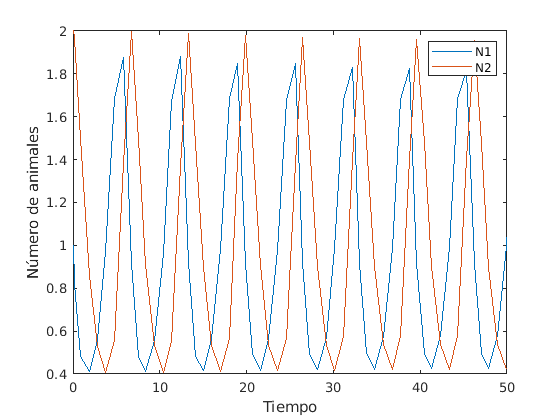

Time = 50;
options = simset('SrcWorkspace','current');
sim('Competencia_SinControl',[],options);

plot(t,SP,t,SD)
xlabel('Tiempo')
ylabel('Número de animales')
legend('N1','N2')